Este programa halla la solución aproximada por el método de Runge Kutta Orden 4 del sistema de ecuaciones diferenciales de primer orden

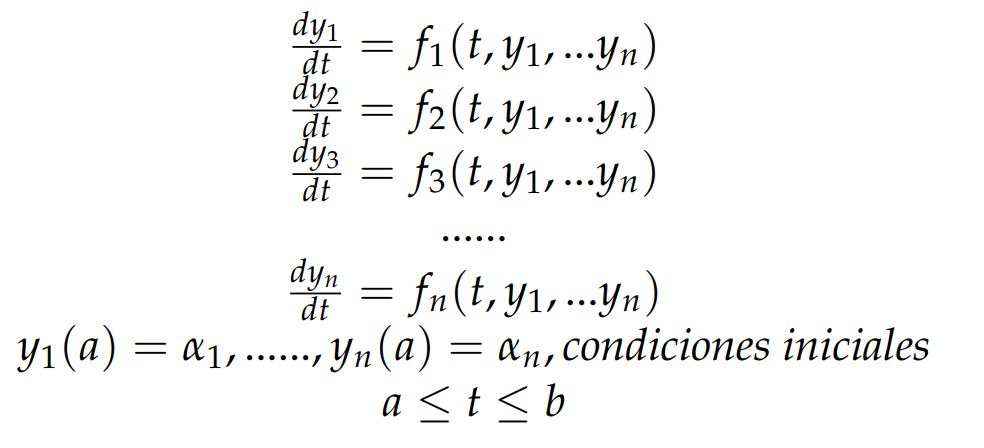

Equivalente al sistema: 

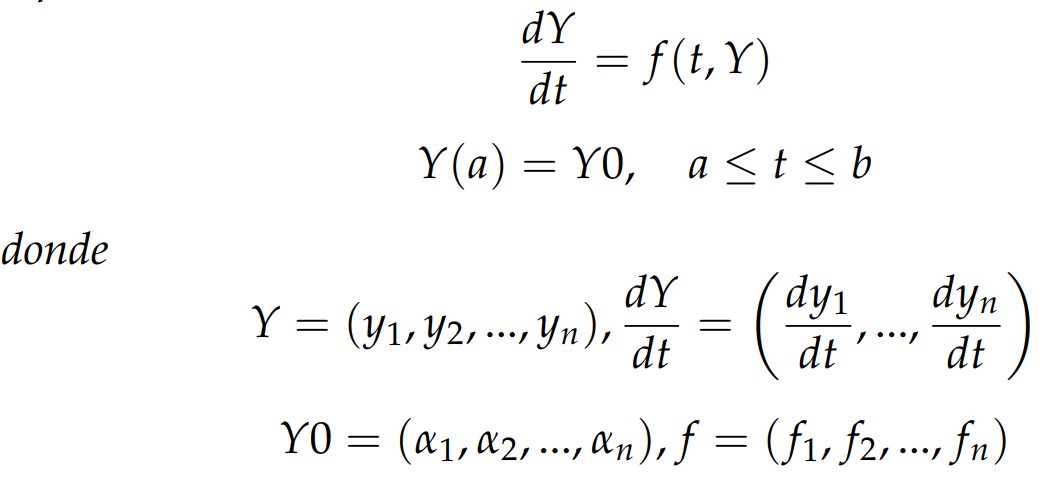

Y0 es el vector renglón de condiciones iniciales

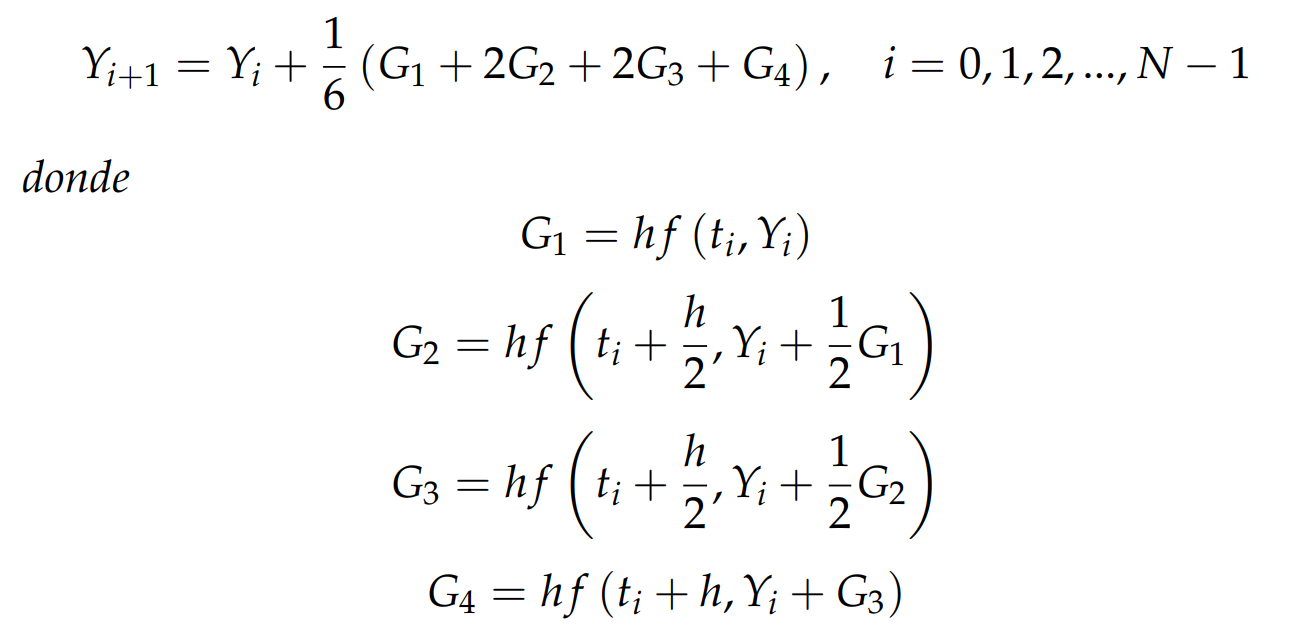

h es el tamaño de paso de la discretización del intervalo [a,b]

v={'t','y1',...,'yn'} arreglo de celdas

function A=RungeKuttaO4_2(f,Y0,a,b,h,v)
N=ceil((b-a)/h);
t=linspace(a,b,N+1); % [a,t+h,...]
n=length(Y0);
Y=zeros(N+1,n);
Y(1,:)=Y0;
for i=1:N
    G1=h*f(t(i),Y(i,:));
    G2=h*f(t(i)+h/2,Y(i,:)+G1/2);
    G3=h*f(t(i)+h/2,Y(i,:)+G2/2);
    G4=h*f(t(i)+h,Y(i,:)+G3);
    Y(i+1,:)=Y(i,:)+(G1+2*G2+2*G3+G4)/6;
end
A=[t' Y];
A=array2table(A,"VariableNames",v);

% Grafica
for k=1:n
    plot(t',Y(:,k),'LineStyle','--');
    xlabel(v(1))
    ylabel('Y')
    legend(v(2:end))
    hold on
end
    hold off